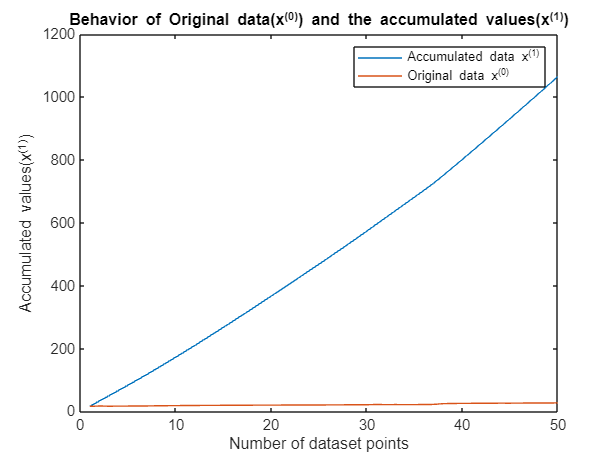

tic
data=readtable("D:\Sem 4\MFC\Project\MFC datasets\Preonzo Landslide dataset.xlsx");
raw_E1=data.E2;
raw_E1=raw_E1(~isnan(raw_E1));
x0=abs(raw_E1);
x0=abs(x0)';
x1=cumsum(x0);
plot(x1(1:50));xlabel("Number of dataset points");ylabel("Accumulated values(x^{(1)})");title("Behavior of Original data(x^{(0)}) and the accumulated values(x^{(1)})");hold on
plot(x0(1:50));
legend("Accumulated data x^{(1)}","Original data x^{(0)}")
hold off

n=size(x0);
n=n(:,2);

L = 5;
x0_hat_meta = zeros(1,n);
x0_hat_meta(1:L) = x0(1:L);
lambda = 0.6;
lambda_r = 0.1;
a=zeros(1,n);
for t = L+1:n
    x0_win = x0(t-L : t-1);
    x1_win = cumsum(x0_win);
    z1 = lambda * x1_win(2:end) + (1-lambda) * x1_win(1:end-1);
    B = [-z1' ones(L-1,1)];
    Y = x0_win(2:end)';
    theta = (B'*B + lambda_r*eye(2)) \ (B'*Y);
    a(t) = theta(1);
    b = theta(2);
    x1_hat = (x1_win(1) - b/a(t)) * exp(-a(t) * (0:L-1)) + b/a(t); 
    x0_hat_meta(t) = x1_hat(end) - x1_hat(end-1);
    Y_hat = B * theta;
    residuals = Y - Y_hat;
    df = (L-1) - 2; 
    sigma_sq = (residuals' * residuals) / df;
    C = sigma_sq * inv(B' * B + lambda_r * eye(2));
    se_a = sqrt(C(1,1));
    se_b = sqrt(C(2,2));
    t_val_a = theta(1) / se_a;
    t_val_b = theta(2) / se_b;
end 
t_val_a

t_val_a = -1.4557

t_val_b

t_val_b = 7.1857

x0=x0(:)';
x0_hat_meta=x0_hat_meta(:)';
res_meta=x0-x0_hat_meta;
E = fft(res_meta);
magE = abs(E);
K=3;
[~, idx] = sort(magE(2:floor(n/2)), 'descend');
idx = idx(1:K) + 1;

E_filt = zeros(size(E));
E_filt(1) = E(1);
E_filt(idx) = E(idx);
E_filt(n-idx+2) = E(n-idx+2);

res_hat_meta = real(ifft(E_filt));

x0_hat_meta_final = x0_hat_meta + res_hat_meta

x0_hat_meta_final =    -0.6077    0.4155   -0.2112    0.0320    0.2353    0.8097    1.1417    1.3117    1.7041    2.0712    2.4512    2.6142    2.7024    3.1205    3.3132    3.4907    3.6017    3.7847    3.9045    4.0459    4.1933    4.2927    4.3852    4.5140    4.6368    4.7172    4.8028    4.9345    5.1459    5.3389    5.5042    5.9177    5.9706    6.0294    5.8972    5.9378    6.0507    6.4102    8.0252    9.2396    9.9601   10.1045   10.2893   10.4875   10.6558   10.6905   10.8504   11.0664   11.1845   11.3404


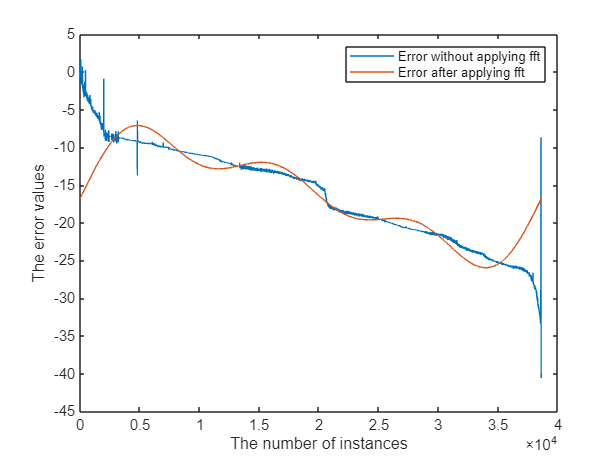

plot(res_meta);hold on
plot(res_hat_meta);legend("Error without applying fft","Error after applying fft");
xlabel("The number of instances");ylabel("The error values");
hold off;

err_meta = x0 - x0_hat_meta_final

err_meta =    16.7277   16.7245   16.7212   16.7180   16.7147   16.4303   16.1983   16.5683   16.4659   16.4388   16.1088   15.9958   16.5876   16.0695   16.0768   16.0493   16.0783   15.9953   16.0255   16.0241   15.9267   15.9273   15.9848   15.9460   15.8732   15.8928   15.9572   16.0655   16.0041   15.9511   16.3758   15.6723   15.7594   15.5106   15.7428   15.8922   16.2193   18.2498   17.1748   16.3504   15.7299   15.7355   15.7907   15.6925   15.4742   15.7295   15.7696   15.5536   15.6755   15.6696


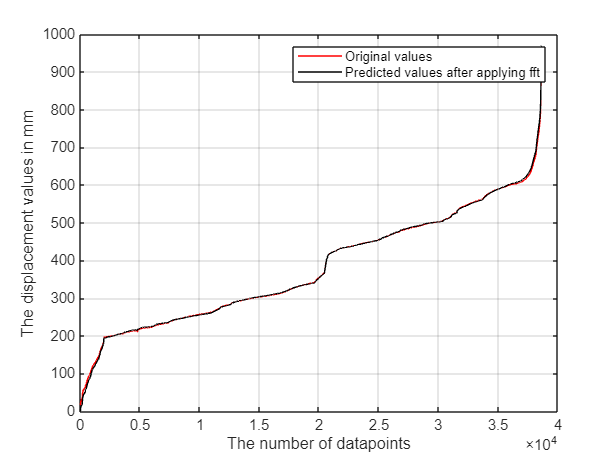

plot(x0,"r");hold on
plot(x0_hat_meta_final,"k");legend("Original values","Predicted values after applying fft");
xlabel("The number of datapoints");ylabel("The displacement values in mm");
hold off
grid on

risk_values_2 = ones(1,n)*1.75;
hazard_level = strings(1,n);
hazard_level(:) = "No Warning";
RC = 0.001;
RT = 1.75;
for k = 2313:n
    num = abs(x0(k) - x0_hat_meta_final(k));
    den = x0(k);
    p_i = num / den;
    accel_factor = abs(a(k));            
    risk_values_2(k) = (p_i * 100) + (accel_factor * 5);
    if risk_values_2(k) > RT
        
        hazard_level(k) = "Advanced Warning";
    else
        hazard_level(k) = "Safe";
    end
end
risk_values_2 = min(risk_values_2, 20);
hazard_level'

ans = 38636×1 string array
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"
    "No Warning"


#### The Original Combined Displacement & Risk Plot(With all values considered)

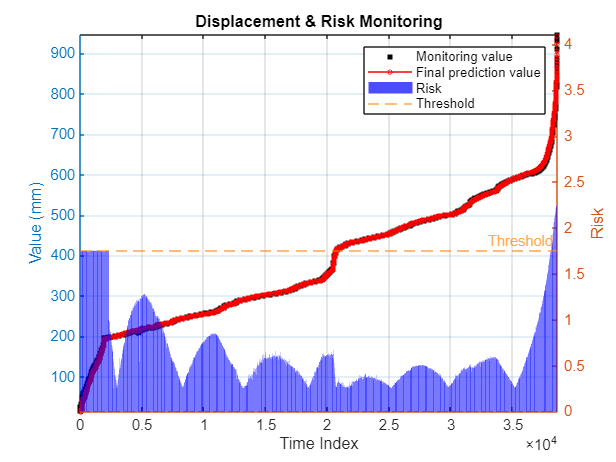

figure;
yyaxis left
plot(x0, 'ks', 'MarkerSize', 4, 'MarkerFaceColor', 'k');
hold on
plot(x0_hat_meta_final, 'r-o', 'MarkerSize', 3);
ylabel('Value (mm)');
ylim([min(x0)-2, max(x0)+2]);
yyaxis right
bar(risk_values_2, 'FaceColor', 'b', 'FaceAlpha', 0.7);
ylabel('Risk');
ylim([0, max(risk_values_2)*1.2]);
hold on
yline(RT, '--', 'Threshold', 'Color', [1 0.5 0]);

xlabel('Time Index');
title('Displacement & Risk Monitoring');

legend('Monitoring value', ...
       'Final prediction value', ...
       'Risk', ...
       'Threshold');

grid on

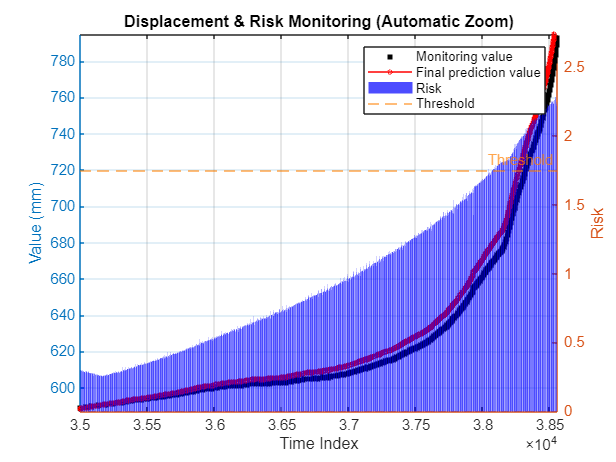

idx = 35000:38559;
idx = idx(idx <= n);
figure;
yyaxis left
plot(idx, x0(idx),'ks','MarkerSize',4,'MarkerFaceColor','k'); hold on
plot(idx, x0_hat_meta_final(idx),'r-o','MarkerSize',3);
ylabel('Value (mm)');
ylim([min(x0(idx))-2 max(x0(idx))+2])
yyaxis right
bar(idx, risk_values_2(idx),'FaceColor','b','FaceAlpha',0.7);
ylabel('Risk');
ylim([0 max(risk_values_2(idx))*1.2])
hold on
yline(RT,'--','Threshold','Color',[1 0.5 0]);

xlabel('Time Index');
title('Displacement & Risk Monitoring (Automatic Zoom)');
legend('Monitoring value','Final prediction value','Risk','Threshold');

grid on

toc

Elapsed time is 2.323202 seconds.


Total time elapsed: `2.323202 seconds.`